# Práctica 6.Implementación de Sistemas de Tiempo Discreto

1. Utilice la función xcorr() de Matlabpara calcularla autocorrelación (𝑚) de la señal


$$x\left(n\right)={\left(\frac{1}{2}\right)}^n \left\lbrack u\left(n\right)-u\left(n-5\right)\right\rbrack$$


Grafique rxx(m)

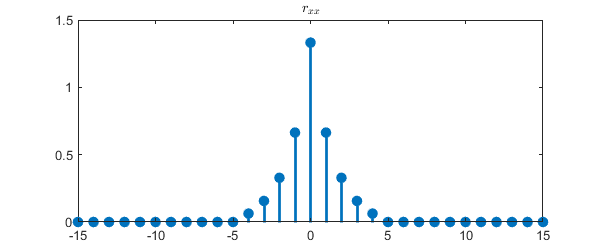

escalon = @(n) n>=0;
n = -15:15;
figure('Position',[500 400 600 250])
x = ((1/2).^n).*( escalon(n)-escalon(n-5) );
[c,lags] = xcorr(x);
stem(lags,c,'filled','LineWidth',2)
title('$r_{xx}$','Interpreter','latex')
xlim([-15 15])

2. Utilice la función xcorr() de Matlab para calcularla correlación cruzada rxy(m) de las señales.


$$y\left(n\right)={\left(\frac{1}{3}\right)}^n \left\lbrack u\left(n\right)-u\left(n-5\right)\right\rbrack \;\;\;\;\;\;\;x\left(n\right)={\left(\frac{1}{2}\right)}^n \left\lbrack u\left(n\right)-u\left(n-5\right)\right\rbrack$$


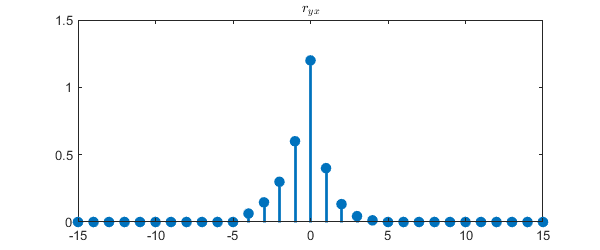

escalon = @(n) n>=0;
n = -15:15;
figure('Position',[500 400 600 250])
x = ((1/2).^n).*( escalon(n)-escalon(n-5) );
y = ((1/3).^n).*( escalon(n)-escalon(n-5) );
[c,lags] = xcorr(y,x);
stem(lags,c,'filled','LineWidth',2)
title('$r_{yx}$','Interpreter','latex')
xlim([-15 15])
ylim([0 1.5])

3. Utilice la  función randn() de   Matlab para   generar una   secuencia aleatoria 𝑥(𝑛) con distribución gaussiana, media   cero,   varianza   uno   y   longitud   150,000.   Determine   la autocorrelación 

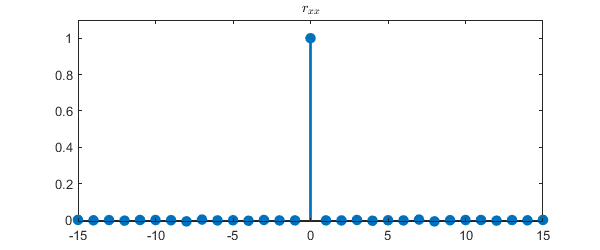

figure('Position',[500 400 600 250])
[rxx,lag]=xcorr(randn (150000,1),15,'normalized');
title('$r_{xx}$','Interpreter','latex')
stem(lag,rxx,"filled","LineWidth",2);
title('$r_{xx}$','Interpreter','latex')
ylim([-.01 1.1])

4. Para el sistema definido por la ecuacion


$$y\left(n\right)-\frac{1}{2}y\left(n-1\right)=x\left(n\right)$$


determine  la correlación cruzada 𝑟𝑦𝑥(𝑚) si la señal de entrada 𝑥(𝑛) es la secuencia aleatoria del inciso (3). Normalice la correlación y grafique el resultado en el intervalo −5<𝑚<5.

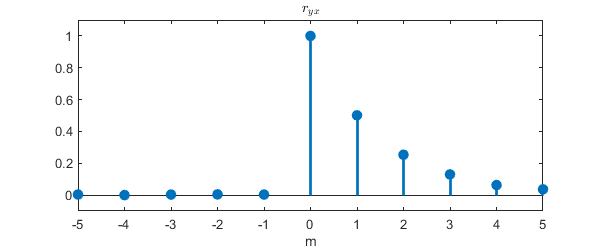

figure('Position',[500 400 600 250])
r = randn (150000,1);
y=filter(1,[1 -1/2],r);
[c,lag]=xcorr(y,r,5,"normalized");
stem(lag,c/max(c),"filled","LineWidth",2);
title('$r_{yx}$','Interpreter','latex')
xlabel('m')
ylim([-.1 1.1])

% Ejericio 1

escalon = @(n) n>=0;

n = -15:15;

figure('Position',[500 400 600 250])

x = ((1/2).^n).*( escalon(n)-escalon(n-5) );

[c,lags] = xcorr(x);

stem(lags,c,'filled','LineWidth',2)

title('$r_{xx}$','Interpreter','latex')

xlim([-15 15])

%Ejercicio 2

escalon = @(n) n>=0;

n = -15:15;

figure('Position',[500 400 600 250])

x = ((1/2).^n).*( escalon(n)-escalon(n-5) );

y = ((1/3).^n).*( escalon(n)-escalon(n-5) );

[c,lags] = xcorr(y,x);

stem(lags,c,'filled','LineWidth',2)

title('$r_{yx}$','Interpreter','latex')

xlim([-15 15])

ylim([0 1.5])

%Ejercicio 3

figure('Position',[500 400 600 250])

[rxx,lag]=xcorr(randn (150000,1),15,'normalized');

title('$r_{xx}$','Interpreter','latex')

stem(lag,rxx,"filled","LineWidth",2);

title('$r_{xx}$','Interpreter','latex')

ylim([-.01 1.1])

%Ejercicio 4

figure('Position',[500 400 600 250])

r = randn (150000,1);

y=filter(1,[1 -1/2],r);

[c,lag]=xcorr(y,r,5,"normalized");

stem(lag,c/max(c),"filled","LineWidth",2);

title('$r_{yx}$','Interpreter','latex')

xlabel('m')

ylim([-.1 1.1])